%Toturial MirrorChern
% 1.根据TB对象的basis生成对应的Mirror算符
% 2.使用TB对象(HR类形式)计算 MirrorBC & MirrorChern
%在构建好Mirror算符后有两种等价的方法计算Mirror_BC
%第一种方法是在计算BC时使用Mz算符并指定子区域划分'subband'
%第二种方法是直接通过Mirror划分出子系统的TB模型即新的小HR类对象再计算BC和Chern


clear;
load('PtCl3.mat'); %读取PtCl3的wannier模型,是一个HR类对象
%注:此处直接用的matlab数据，一般读取wannier90数据使用方法如下
% PtCl3=HR.from_wannier90('wannier90_hr.dat.full_group');里面是hr.dat的文件名

% Mirror_construct 构造Mz矩阵
%支持读取wannier90.wout和HR类对象两种输入方式

%读取方式11，读取wannier90.wout
Mz1 = Mirror_construct( ...
    'mode','spinful',...  %构建模式，spinful或spinless,默认Spinful
    'source', 'wout', ... %通过读取wannier90.wout获取信息构建Mz
    'Mirror','Mz',... %构建的算符,可选Mx,My,Mz，默认Mz
    'Mirror_plane', [0 0 0.5], ... %镜面,默认为z=0.5
    'filename','wannier90.wout',... %要读取的wannier90.wout文件名
    'POSCAR_name','POSCAR'); %使用到的POSCAR


%读取方式22,读取某个HR类，可以是wannier90_hr.dat转换的也可以是自己搭建的模型

%重要信息:HR.orbL 每个Basis的实空间位置
% HR.quantumL 每列分别对应Basis的[n,l,m,sz]
% HR.elementL 每个Basis的元素
%它们的维度(行数)应当相等，当维度不等时要检查，例如是否考虑quantumL的自旋分量等
Mz2 = Mirror_construct( ...
    'mode','spinful',...  %构建模式，spinful或spinless
    'source', 'HR', ... %通过读取wannier90.wout获取信息构建Mz
    'HR',PtCl3,...%读取的HR对象!！!注意检查其orbL,elementL,quantumL的基矢信息是否正确,例如维度和自旋
    'Mirror','Mz',... %构建的算符,可选Mx,My,Mz
    'Mirror_plane', [0 0 0.5], ... %镜面 z=0.5
    'POSCAR_name','POSCAR'); %使用到的POSCAR


BAND calculating 153/153 ...


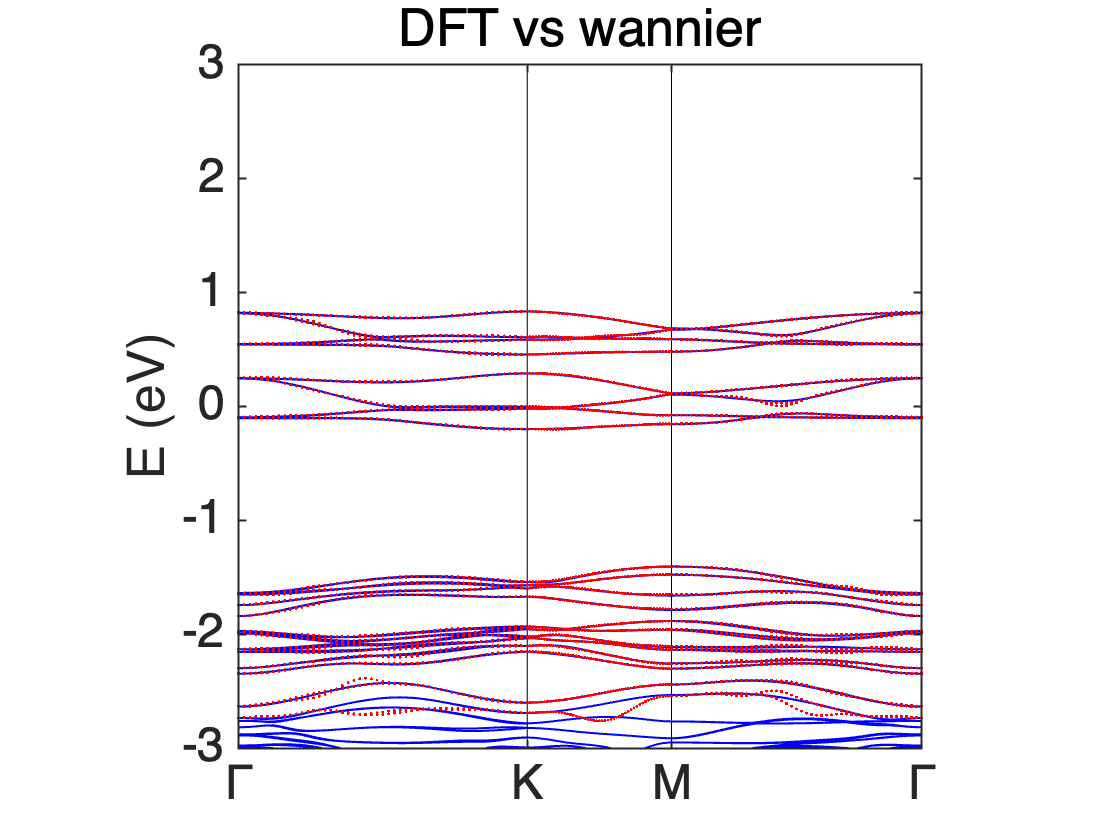

%对比DFT能带和拟合出的wannier模型的能带
EIGENCAR_DFT =EIGENVAL_read;%读取DFT能带
bandcompare(PtCl3.EIGENCAR_gen,EIGENCAR_DFT,'Title','DFT vs wannier');%根据PtCl3的模型生成能带并对比

%计算BC需要知道wannier的占据带具体有多少条
Ef= 0;%band_index可通过计算wannier能带来查看和选取
EIGENCAR_wan=PtCl3.EIGENCAR_gen() - Ef;%这里读取的模型已经调整过了，有时需要根据DOSCAR或OUTCAR查看费米能进行调节

BAND calculating 153/153 ...


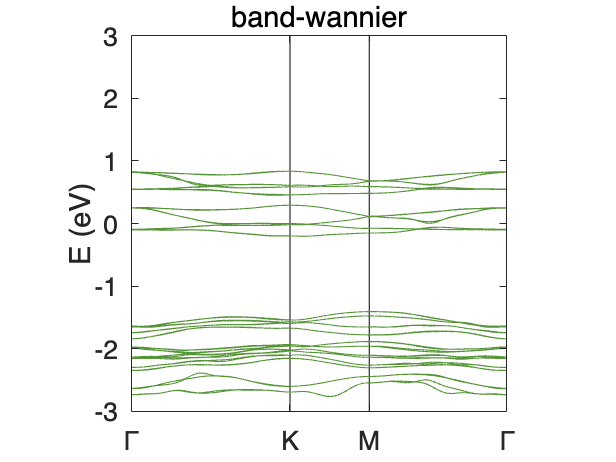

bandplot(EIGENCAR_wan, [-3,3]); %数能带或查看EIGENCAR_wan获得占据能带数
title('band-wannier')   %可发现此wannier模型占据带为28/40

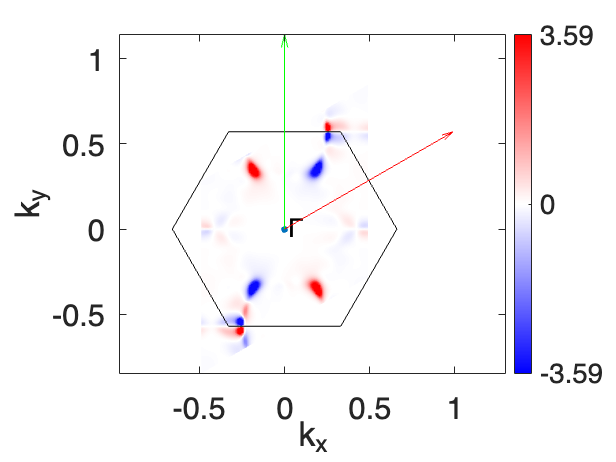

tic;     
[BCCAR1,Grid] =PtCl3.BC_2D('knum1',101,'knum2',101,'BAND_index',1:28); %生成HR类对象TB模型的Berry-Curv
BCplot2D(BCCAR1,Grid,double(PtCl3.Rm),'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);%shading(gca,'interp');

toc;

历时 7.690988 秒。


fprintf("Chern number of PtCl3-AA'-AFM(y) = %f",sum(BCCAR1,'all')/(2*pi));%根据BC得到Chern

Chern number of PtCl3-AA'-AFM(y) = -0.000000

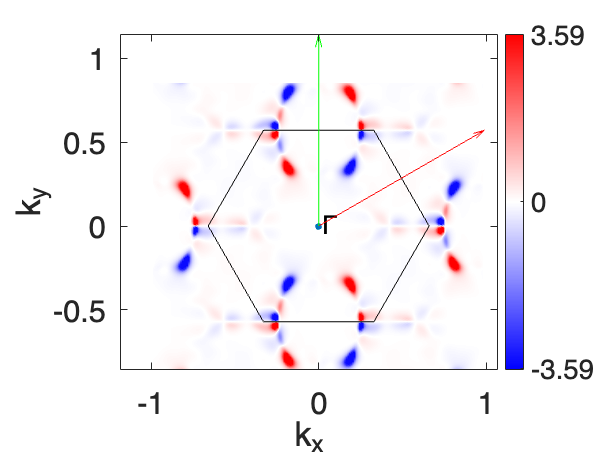

[klist_expand,BCCAR_expand] = kshift(Grid,[-1,-0.25,0;2,-1,0;0,1.5,0],BCCAR1,'cart',true,'Rm',PtCl3.Rm);
BCplot2D(BCCAR_expand,klist_expand,PtCl3.Rm,'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);

%在计算Mirror BC之前，需要知道占据带在两个镜面子系统里各占多少带
%使用pbandplot绘制Mz投影能带从而进行查看
[EIGENCAR_Mz,~,WEIGHTCAR_Mz] = PtCl3.EIGENCAR_gen("Oper",Mz1.U);  %WEIGHTCAR为对应能带上各点波函数对Oper矩阵的本征值

BAND calculating 153/153 ...


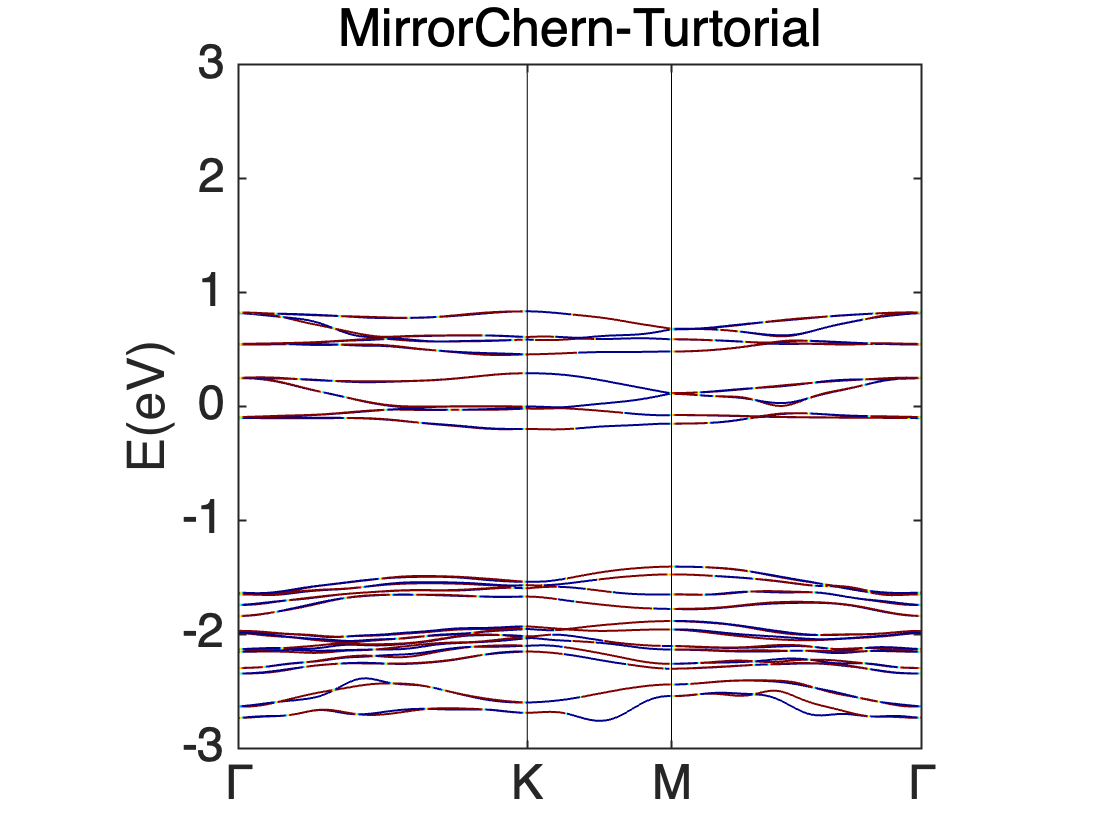

WEIGHTCAR=imag(WEIGHTCAR_Mz); %注意画投影能带的权重需要是实的，此处本征值是i和-i所以提取了虚步
pbandplot(real(WEIGHTCAR),EIGENCAR_Mz,'Ecut',[-3,3],'KPOINTS','KPOINTS','cmap',@jet);

%这一步目的是获得信息'BAND_index'即各子系统有多少占据带,后面算MirrorBC需要

%可以直接通过对Mz矩阵的特征值求解，查看两个子系统各自是多少维的
[Vmz,Dmz ] = eig(Mz1.U);
Mz_EigVal=diag(Dmz);

%这一步的目的是获得信息'subband',在求解BC_2D的时候会对basis根据Mz本征值重排(会把相同子系统的排在一起，只需要关注数量)
%例如此处查看Mz_EigVal发现i子系统为20维，-i子系统也是20维，则'subband'可以选为1:20或21:40

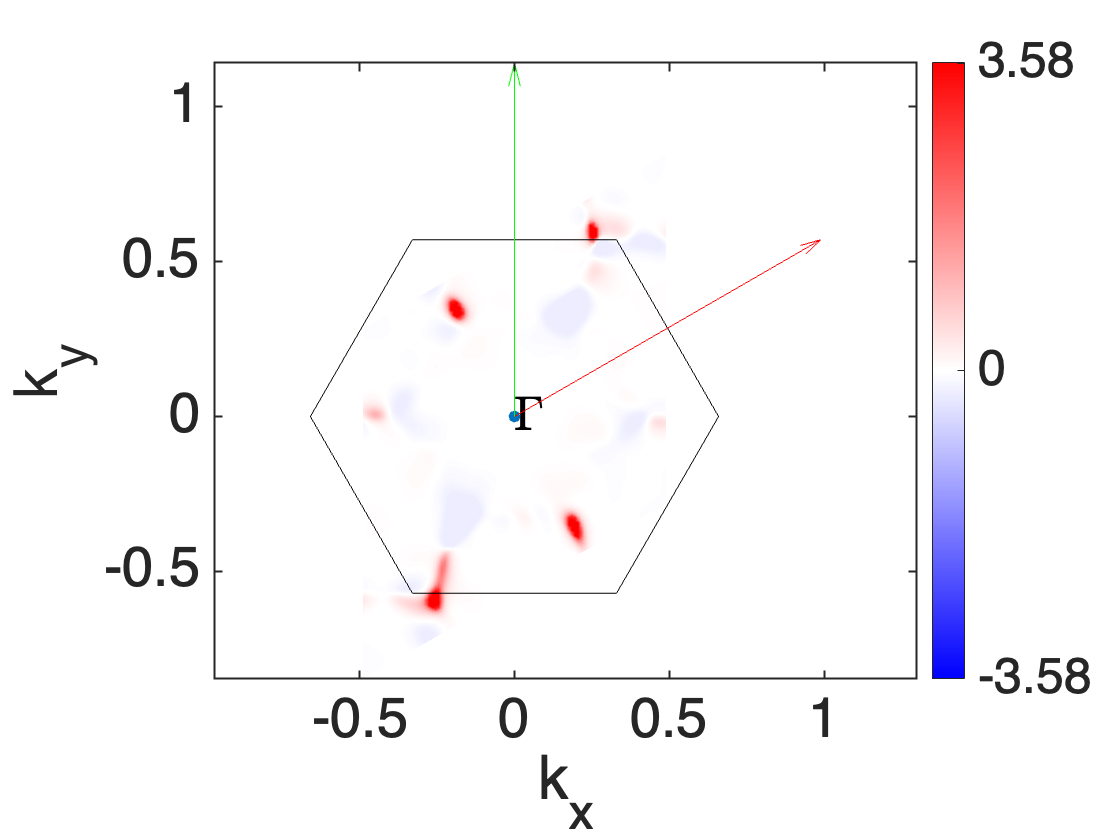

%使用算符计算MirrorBC
[BCCAR2,Grid] =PtCl3.BC_2D('knum1',101,'knum2',101,'BAND_index',1:14,'Oper',Mz1); %subband默认是前一半，有时两个子系统维度不同要自行设定
BCplot2D((BCCAR2),Grid,double(PtCl3.Rm),'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);

fprintf("Mirror(-i) Chern number of PtCl3-AA'-AFM(y) = %f",sum(BCCAR2,'all')/(2*pi));

Mirror(-i) Chern number of PtCl3-AA'-AFM(y) = 1.000000

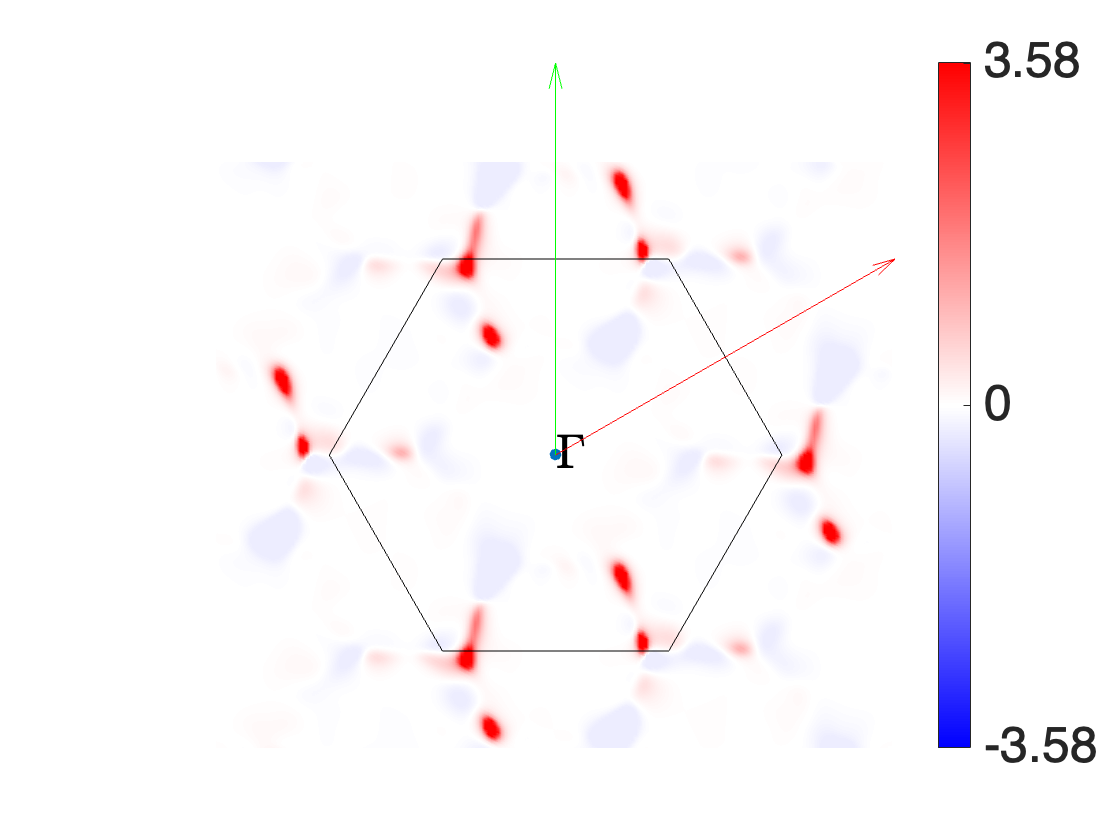

[klist_expand,BCCAR_expand] = kshift(Grid,[-1,-0.25,0;2,-1,0;0,1.5,0],BCCAR2,'cart',true,'Rm',PtCl3.Rm);
BCplot2D(BCCAR_expand,klist_expand,PtCl3.Rm,'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);axis off

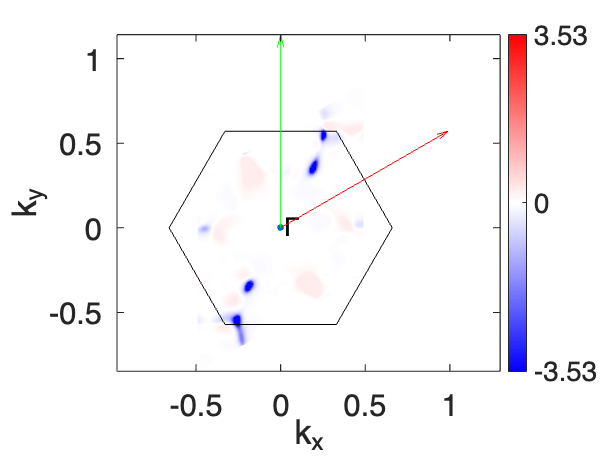

[BCCAR3,Grid] =PtCl3.BC_2D('knum1',101,'knum2',101,'BAND_index',1:14,'Oper',Mz1,'subband',21:40);%21:40，另一个Mz子系统
BCplot2D(BCCAR3,Grid,double(PtCl3.Rm),'BZ',true,'BZmode','2D','ColorCut',0.0514,'shading',true);

fprintf("Mirror(i) Chern number of PtCl3-AA'-AFM(y) = %f",sum(BCCAR3,'all')/(2*pi));

Mirror(i) Chern number of PtCl3-AA'-AFM(y) = -1.000000

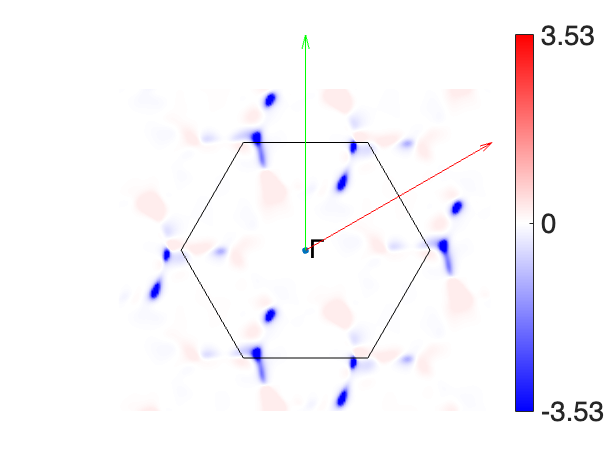

[klist_expand,BCCAR_expand] = kshift(Grid,[-1,-0.25,0;2,-1,0;0,1.5,0],BCCAR3,'cart',true,'Rm',PtCl3.Rm);
BCplot2D(BCCAR_expand,klist_expand,PtCl3.Rm,'BZ',true,'BZmode','2D','ColorCut',0.0514,'shading',true);axis off

%-------------方法2，直接提取子系统的TB模型(两个小的HR类)-------
[HR_list,eig_list]=subsystem_construct(PtCl3,Mz1) %根据Mz对称性,将HR模型PtCl3分成两个对应不同Mz本征值的子系统HR

共识别出 2 个子空间，对应本征值为：
  子系统 1: 本征值 ≈ 0+1i
  子系统 2: 本征值 ≈ 0-1i


HR_list = 1×2 cell 数组
    {1×1 HR}    {1×1 HR}


eig_list =                           0 +                     1i                          0 -                     1i


HR_plus=HR_list{1}; % Mz=i的子系统HR
HR_minus=HR_list{2}; % Mz=-i的子系统HR
%对两个子系统分别计算能带，与之前做的总系统能带进行Mz投影进行对照比较，结果一致
ei_wan_plus = HR_plus.EIGENCAR_gen() ;%子系统能带各点能量本征值，可用来查看子系统占据带数量

BAND calculating 153/153 ...


ax=bandplot(ei_wan_plus, [-3,3], 'LineWidth', 2,  'Color', [1 0 0],'LineSpec', '-');
ei_wan_minus = HR_minus.EIGENCAR_gen() ;%两个子系统能带占据都是14/20

BAND calculating 153/153 ...


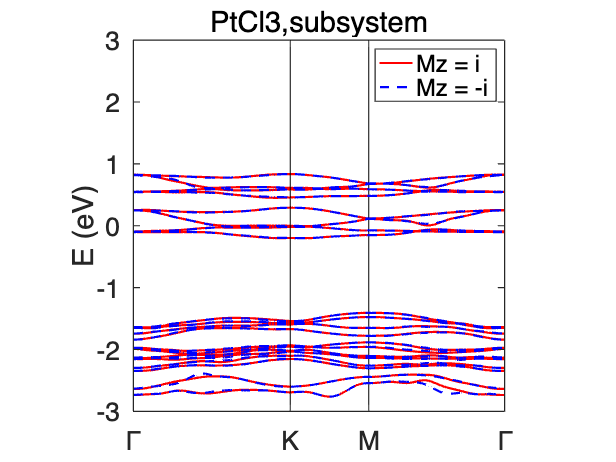

bandplot(ei_wan_minus, [-3,3], 'LineWidth', 2,  'Color', [0 0 1],'LineSpec', '--','ax',ax);
hline1 = findobj(ax, 'Type','Line','Color',[1 0 0]);  
hline2 = findobj(ax, 'Type','Line','Color',[0 0 1]);
h1 = hline1(1);
h2 = hline2(1);
legend(ax, [h1, h2], {'Mz = i', 'Mz = -i'});
title('PtCl3,subsystem')

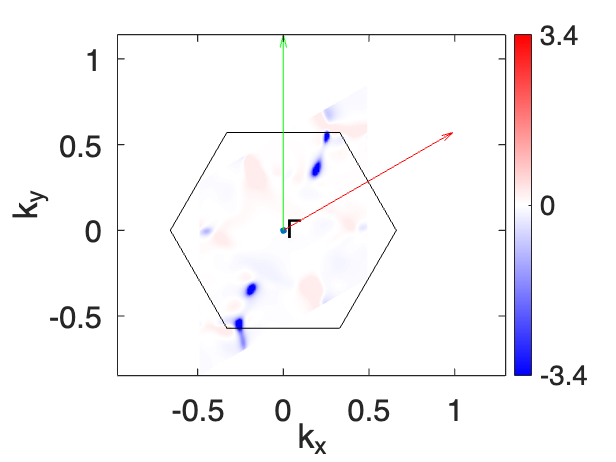

%Mz子系统的BC和Chern，即总系统的MirrorBC和MirrorChern
%Mz=i的子系统
[BCCAR_plus,Grid] =HR_plus.BC_2D('knum1',101,'knum2',101,'BAND_index',1:14); %根据Mz算符，计算PtCl3的Mirror-BC
BCplot2D((BCCAR_plus),Grid,double(HR_plus.Rm),'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);

fprintf("Mirror(i) Chern number of PtCl3-AA'-AFM(y) = %f",sum(BCCAR_plus,'all')/(2*pi));

Mirror(i) Chern number of PtCl3-AA'-AFM(y) = -1.000000

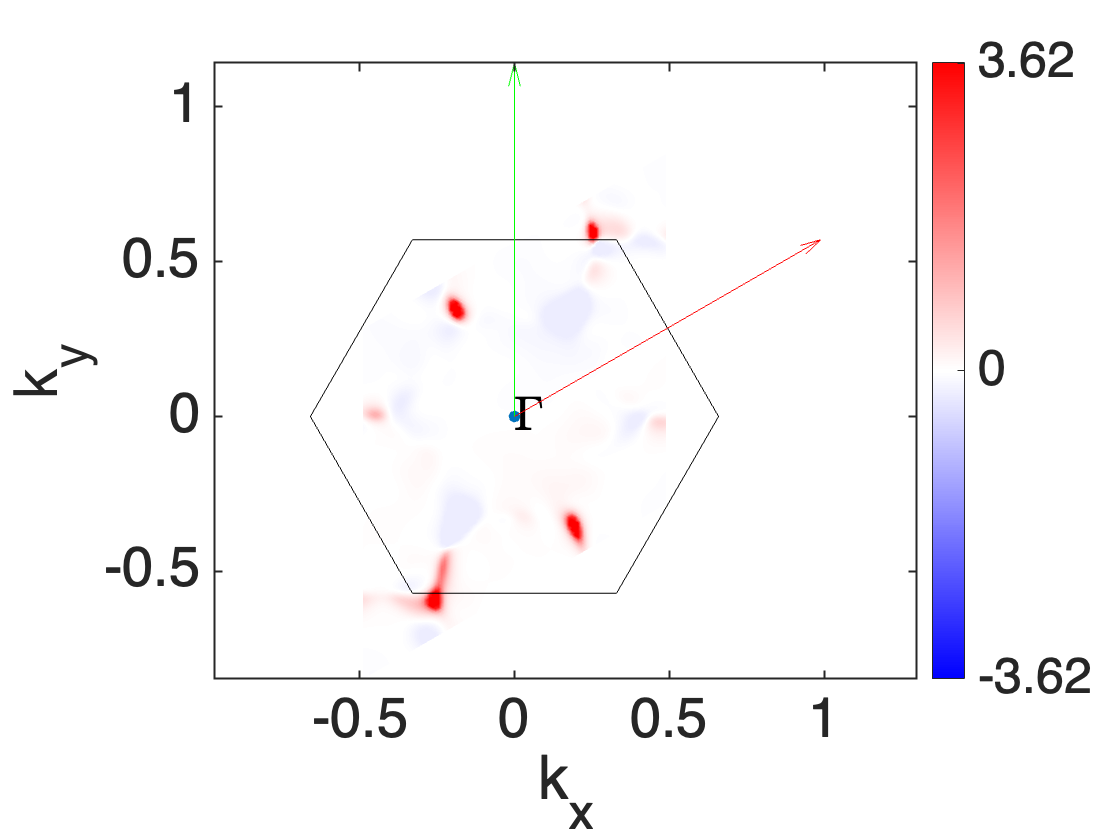

%Mz=-i的子系统
[BCCAR_minus,Grid] =HR_minus.BC_2D('knum1',101,'knum2',101,'BAND_index',1:14); 
BCplot2D((BCCAR_minus),Grid,double(HR_minus.Rm),'BZ',true,'BZmode','2D','ColorCut',0.05,'shading',true);

fprintf("Mirror(-i) Chern number of PtCl3-AA'-AFM(y) = %f",sum(BCCAR_minus,'all')/(2*pi));

Mirror(-i) Chern number of PtCl3-AA'-AFM(y) = 1.000000